# **Discrete-time sinusoids**

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Winter 2018.

## **Discrete-time frequencies**

We've seen analytically that only frequencies between 0 and $2\pi$ are unique in discrete time. Let's see why graphically.

Let's try first $\omega = \pi/4$, and we'll plot both the discrete-time function x[n] and its continuous-time "envelope" function x(t).

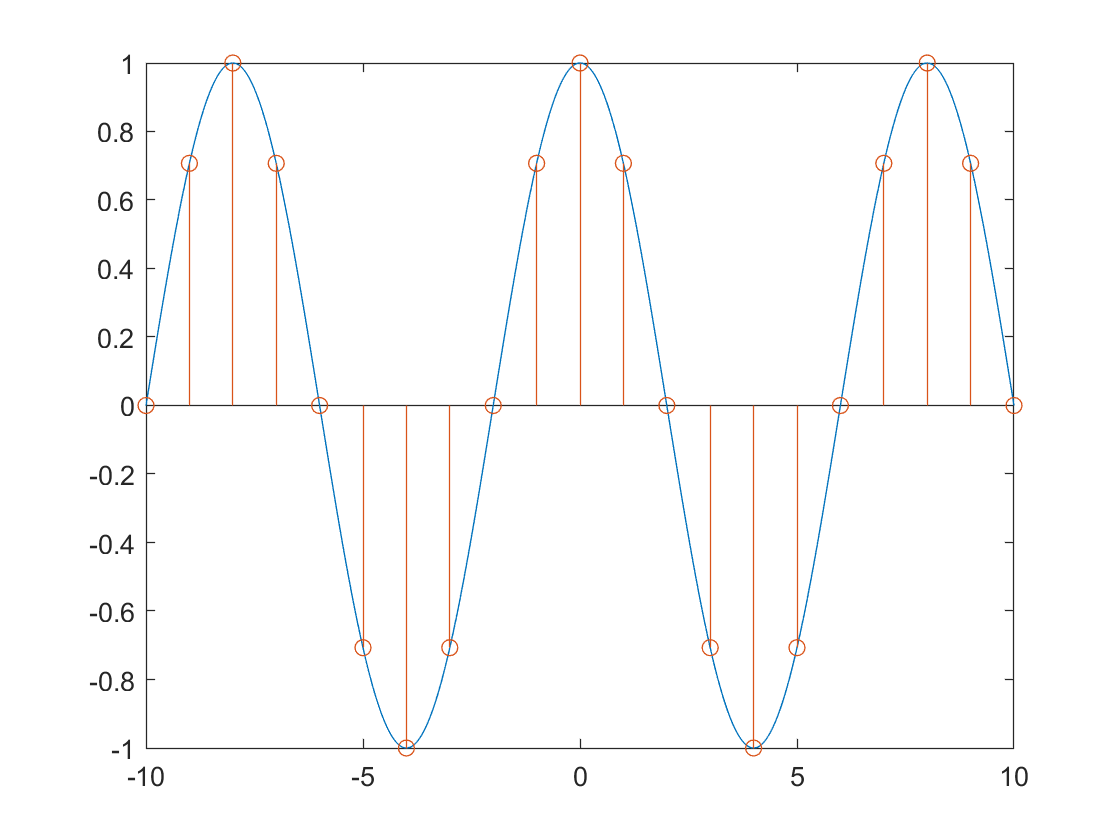

SAMPLE_RATE = 10^2;

nmin = -10;
nmax = 10;
tValues = nmin:1/SAMPLE_RATE:nmax;
nValues = nmin:nmax;
omega = 2*pi*(1/8); %Choose a small discrete-time frequency
xContinous = cos(omega*tValues);
xDiscrete = cos(omega*nValues);

close all;
plot(tValues,xContinous);
hold on;
stem(nValues,xDiscrete);
hold off;

Looks like we'd expect. Let's increase the frequency to $\omega = \pi$.

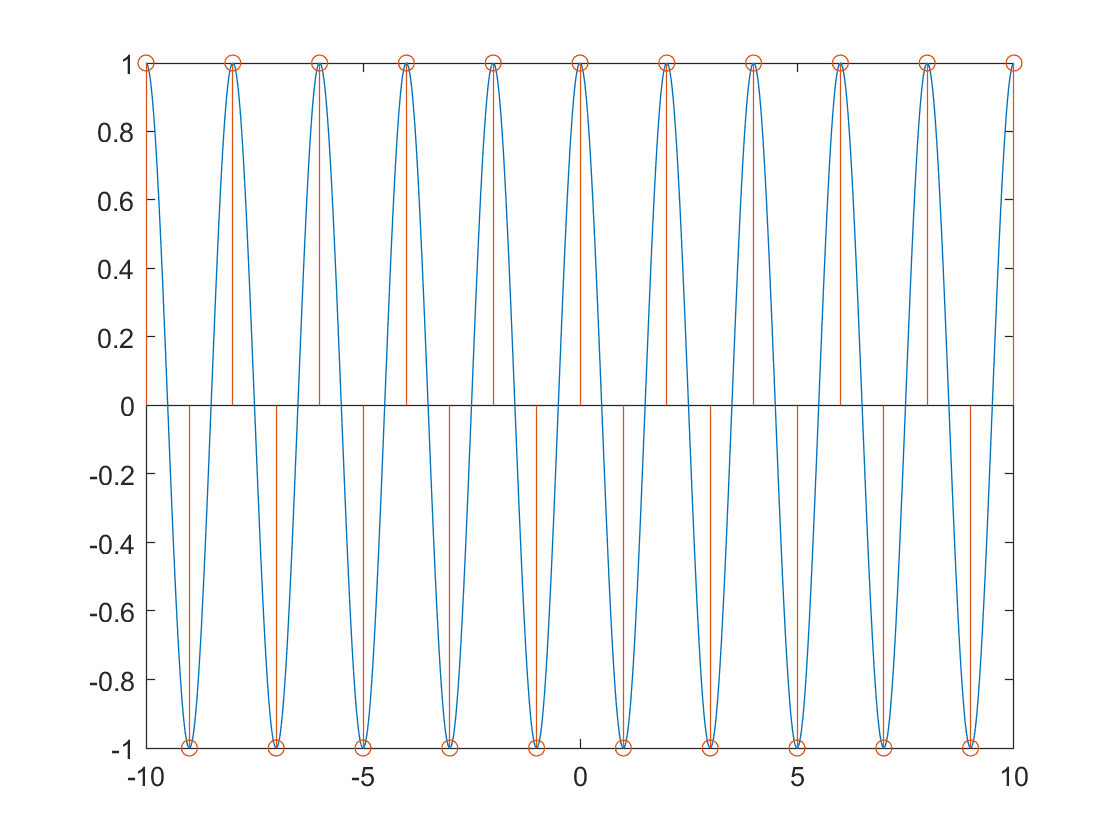

tValues = nmin:1/SAMPLE_RATE:nmax;
nValues = nmin:nmax;

omega = 2*pi*(1/2); %Choose a bigger discrete-time frequency
xContinous = cos(omega*tValues);
xDiscrete = cos(omega*nValues);

close all;
plot(tValues,xContinous);
hold on;
stem(nValues,xDiscrete);
hold off;

This signal alternates every sample. What is the period of this signal? What would a shorter period look like? Let's see what happens when we up the frequency even further, this time to $\omega = 5\pi/4$.

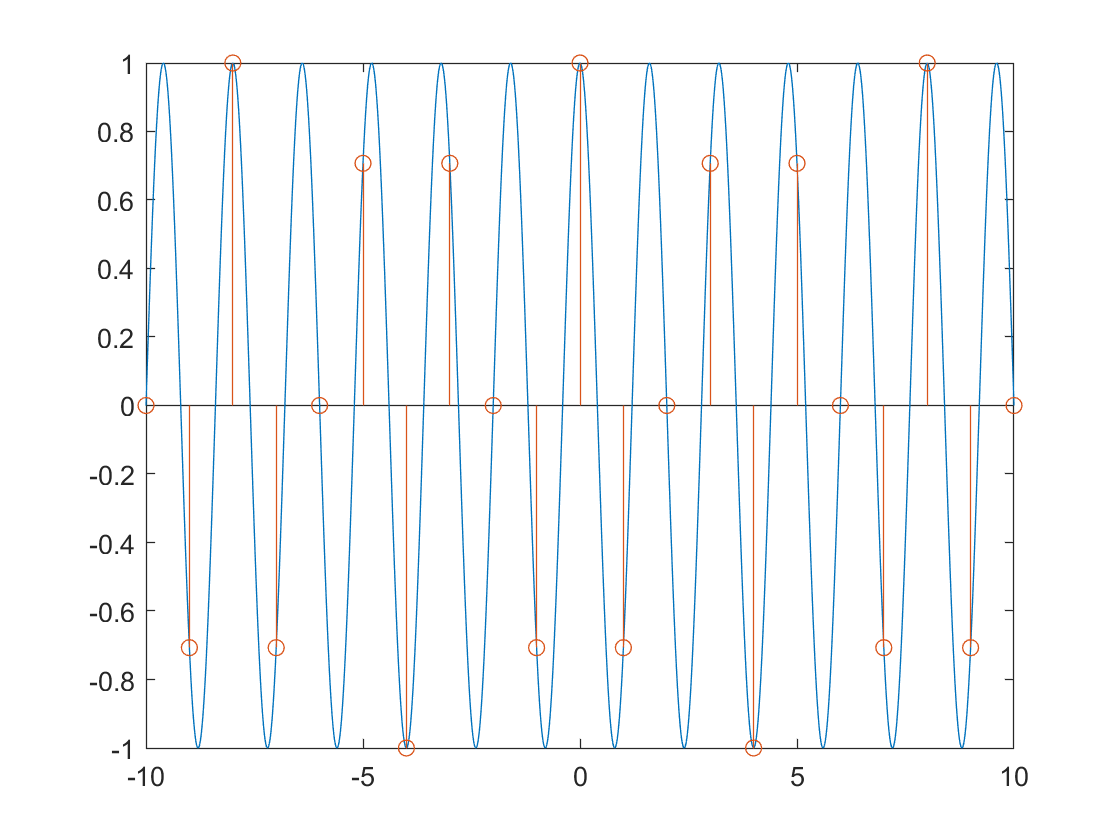

tValues = nmin:1/SAMPLE_RATE:nmax;
nValues = nmin:nmax;
omega = 5*pi/4; %Choose an "even bigger" discrete-time frequency
xContinous = cos(omega*tValues);
xDiscrete = cos(omega*nValues);

close all;
plot(tValues,xContinous);
hold on;
stem(nValues,xDiscrete);
hold off;

Huh. The period didn't get smaller -- it got bigger! Why?

Let's go one further, and take $\omega = 2\pi$.

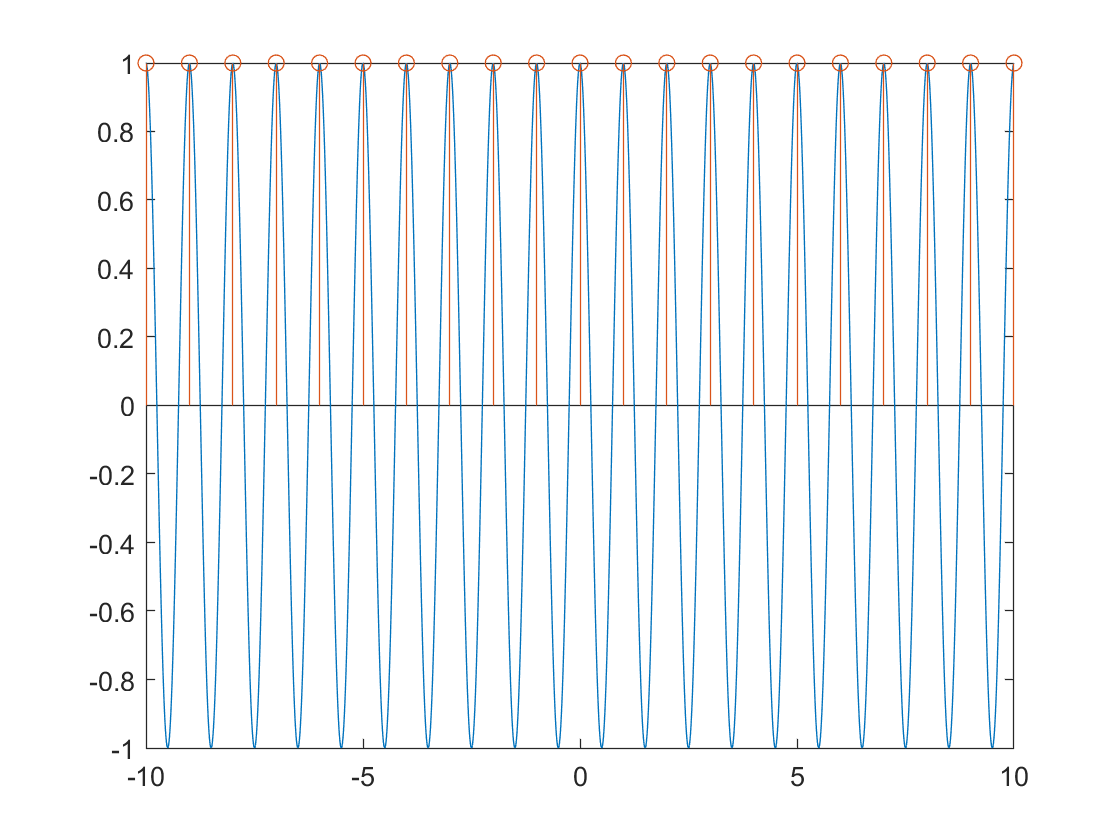

tValues = nmin:1/SAMPLE_RATE:nmax;
nValues = nmin:nmax;
omega = 2*pi; %Choose an "even bigger" discrete-time frequency
xContinous = cos(omega*tValues);
xDiscrete = cos(omega*nValues);

close all;
plot(tValues,xContinous);
hold on;
stem(nValues,xDiscrete);
hold off;

This function is a constant! The underlying sinusoid varies so quickly that we "miss" every other peak, and so we only sample at the values of the cosine such that it equals 1.

This will always be the case. If we increase $\omega$ by $2\pi$, all we do is add variations that will not be sampled in discrete-time. As a final example, let's go back to $\pi/4$ and add a multiple of $2\pi$.

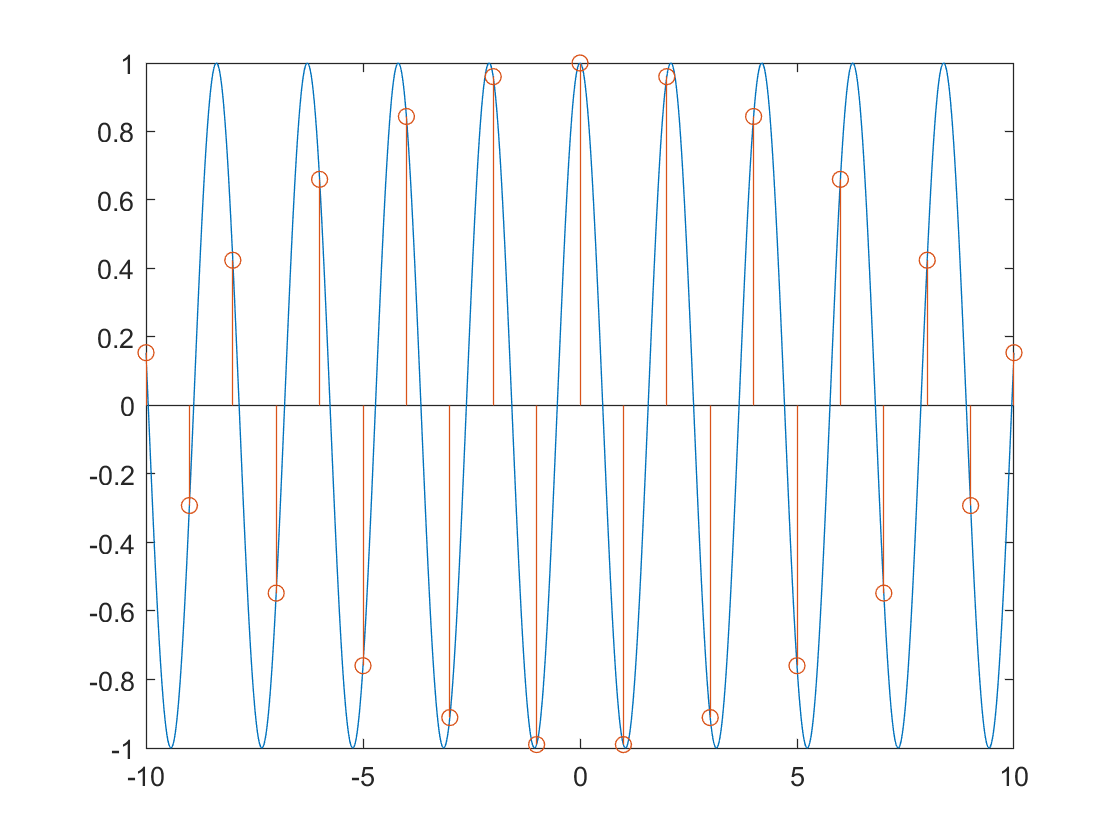

tValues = nmin:1/SAMPLE_RATE:nmax;
nValues = nmin:nmax;
omega = pi/4 + 2*pi; %Add a multiple of 2pi to the frequency
xContinous = cos(omega*tValues);
xDiscrete = cos(omega*nValues);

close all;
plot(tValues,xContinous);
hold on;
stem(nValues,xDiscrete);
hold off;

Sure enough, the underlying continuous-time sinusoid gets faster, but the resulting discrete-time sinusoid stays the same.

Finally, let's see what happens is $\omega$ is not a rational multiple of $\pi$.

tValues = nmin:1/SAMPLE_RATE:nmax;
nValues = nmin:nmax;
omega = 3; %choose something such that the period is irrational!
xContinous = cos(omega*tValues);
xDiscrete = cos(omega*nValues);

close all;
plot(tValues,xContinous);
hold on;
stem(nValues,xDiscrete);
hold off;

Each sample in x[n] catches the sinusoid at a different spot along its period. Because the period of x(t) is not rational, *every single sample* x[n] will catch a different spot on the cycle -- it will never repeat! So, even though x[n] *looks* like a sinusoid, it is not periodic.